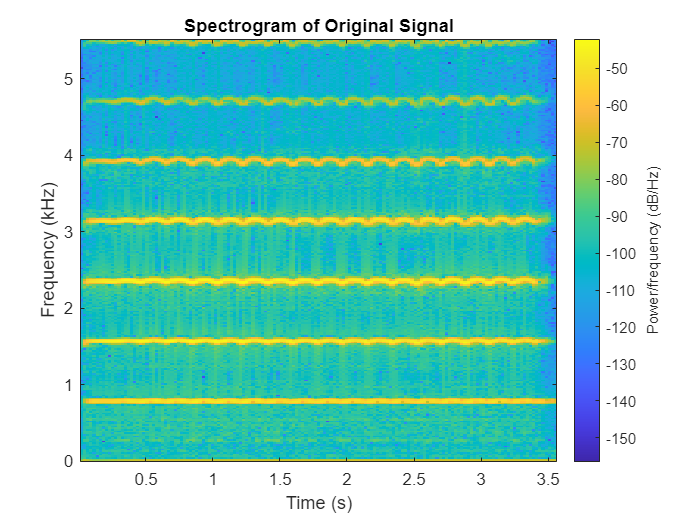

[x, Fs] = audioread('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-7\instru2.wav');
figure;
spectrogram(x, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Original Signal');

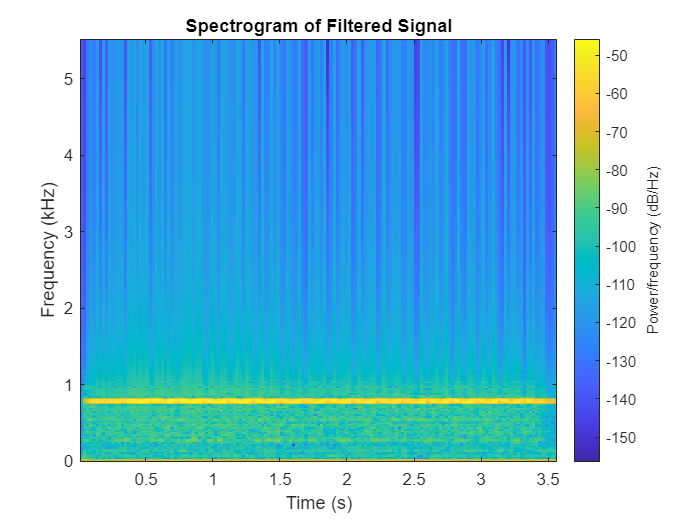


filter_order = 100;
cutoff_freq = 1000;
desired_response = [1, zeros(1, filter_order - 1)];

b = fir1(filter_order, cutoff_freq / (Fs/2), 'low', blackman(filter_order+1));
filtered_signal = filter(b, 1, x);

audiowrite('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-7\filtered_instru2.wav', filtered_signal, Fs);
sound(filtered_signal, Fs);

figure;
spectrogram(filtered_signal, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Filtered Signal');